% POLICY SEARCH FORZADO -- > u=-K*x+k1+k2*x(2)^3;

clc;clear all;close all;
z0=rand(4,1)% ---> fila de 1 x (nx*nu)

z0 =     0.8173
    0.8687
    0.0844
    0.3998


syms x [2 1]
syms u 
syms t

A=jacobian(pend(t,x,u),x);
B=jacobian(pend(t,x,u),u);

xd=[zeros(2,1)]; % --> zeros(nx,1)
ud=[zeros(1,1)]; %---> zeros(nu,1)

A=double(subs(A,[x;u],[xd;ud]))

A =      0     1
     0     0


B=double(subs(B,[x;u],[xd;ud]))

B =      0
     1



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


zopt =    24.4672
   41.2818
   77.9864
    2.2756


Jopt = 714.9661

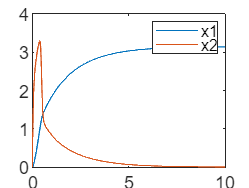



i = 4;
[zopt,Jopt]=fmincon(@(z)costo(z,i),z0,[],[],[],[],[],[],@(z)restr(z,A,B))
x0=[0;0]; % ---> modificar X0
[T,X]=ode45(@(t,x)pend(t,x,control(t,x,zopt)),[0 10],x0); % -->[t0 tn]
plot(T,X(:,1));hold on;
plot(T,X(:,2));
% plot(T,X(:,3));
legend('x1','x2')


function J=costo(z,i)
    fun=@(t,x)pend(t,x,control(t,x,z));
    Ts=0.01;
    T=(0:Ts:4)';
    xk=[0;0];  % ---> X0=[;;;]
    Y=[];
    U=[];
    for k=1:length(T);
        U=[U;control(k*Ts,xk,z)];
        k1=fun(k*Ts,xk);
        k2=fun(k*Ts+Ts/2,xk+k1*Ts/2);
        k3=fun(k*Ts+Ts/2,xk+k2*Ts/2);
        k4=fun(k*Ts+Ts,xk+k3*Ts);
        xk=xk+Ts*(k1+2*k2+2*k3+k4)/6;
        Y=[Y,eye(2)*xk];%----> modificar las salidas (eye(ny))
    end
    Yref=[pi;0]; %----> modificar referencia
    if(i==1)
        J=sum(abs(Y-Yref))+0.01*sum((U.^2));
    elseif(i==2)
        J=sum(abs(Y-Yref).*T)+0.01*sum((U.^2));
    elseif(i==3)
        J=sum((Y-Yref).^2)+0.01*sum((U.^2));
    elseif(i==4)
        J=sum(sum((Y-Yref).^2)'.*T)+0.01*sum((U.^2));
    end
end

function [c,c_eq]=restr(z,A,B)
    K = z(1:(1*2)); %---->z(1:(nu*nx))
    K=reshape(K,[1 2]);% ---> modificar [nu nx]
    c=[max(real(eig(A-B*K)))+0.2];%% +2
    c_eq=[];
end
function u=control(t,x,z)
    k = z(1:(1*2)); %---->  z(1:(nu*nx))
    k1 = z(3); %--->  z((2*3)+(1:2))
    k2 = z(4);
    K=reshape(k,[1 2]);% ---> reshape(k,[2 3])
    u=-K*x+k1+k2*x(2)^3;
end

function dx=pend(t,x,u)
    dx=[x(2);
        u+cos(x(1))];
end


